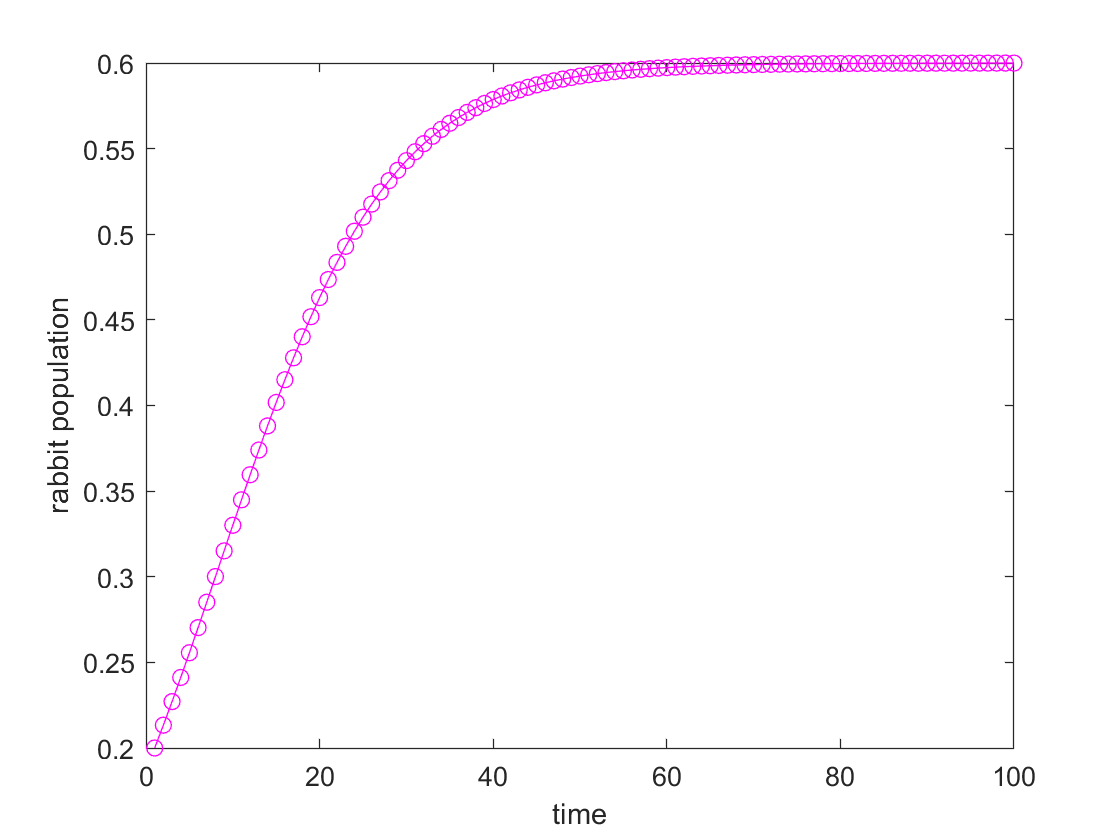

%part c
r = 0.1;
K = 0.6;
time_len = 1:100;

x = zeros(1, length(time_len));

%initial condition (i.e. starting population)
x(1) = 0.2;

for n = 1:length(time_len)-1
    x(n+1) = x(n) + r * (1 - x(n) / K) * x(n);
end

figure;
plot(time_len, x, '-om')
xlabel('time')
ylabel('rabbit population')

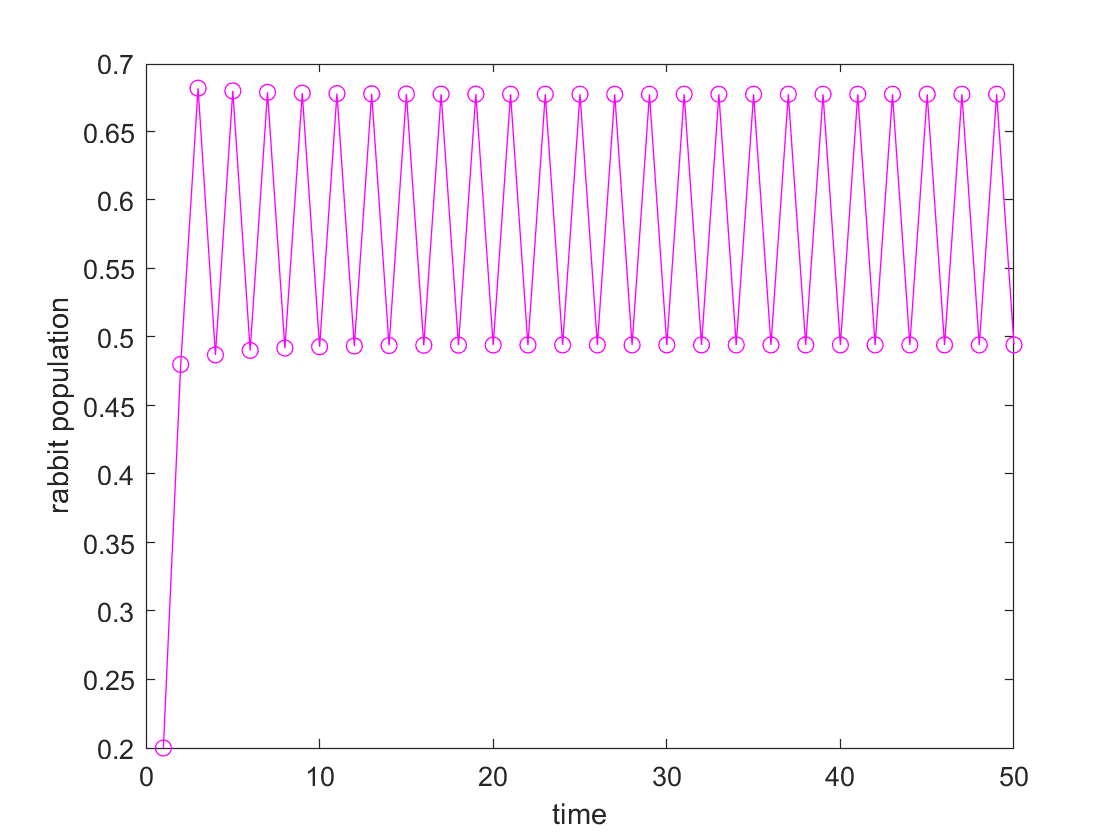

%part d
r = 2.1;
K = 0.6;
time_len = 1:50;

x = zeros(1, length(time_len));

%initial condition (i.e. starting population)
x(1) = 0.2;

for n = 1:length(time_len)-1
    x(n+1) = x(n) + r * (1 - x(n) / K) * x(n);
end
figure;
plot(time_len, x, '-om')
xlabel('time')
ylabel('rabbit population')

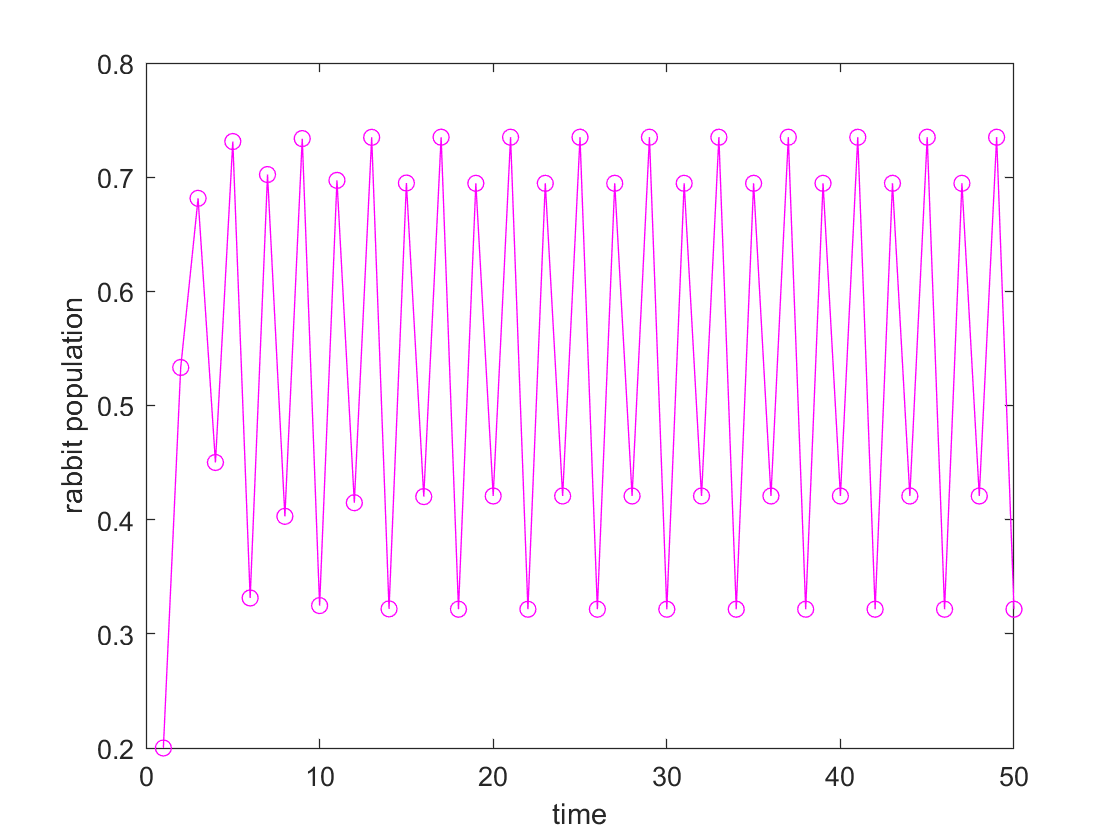

%part e
r = 2.5;
K = 0.6;
time_len = 1:50;

x = zeros(1, length(time_len));

%initial condition (i.e. starting population)
x(1) = 0.2;

for n = 1:length(time_len)-1
    x(n+1) = x(n) + r * (1 - x(n) / K) * x(n);
end
figure;
plot(time_len, x, '-om')
xlabel('time')
ylabel('rabbit population')

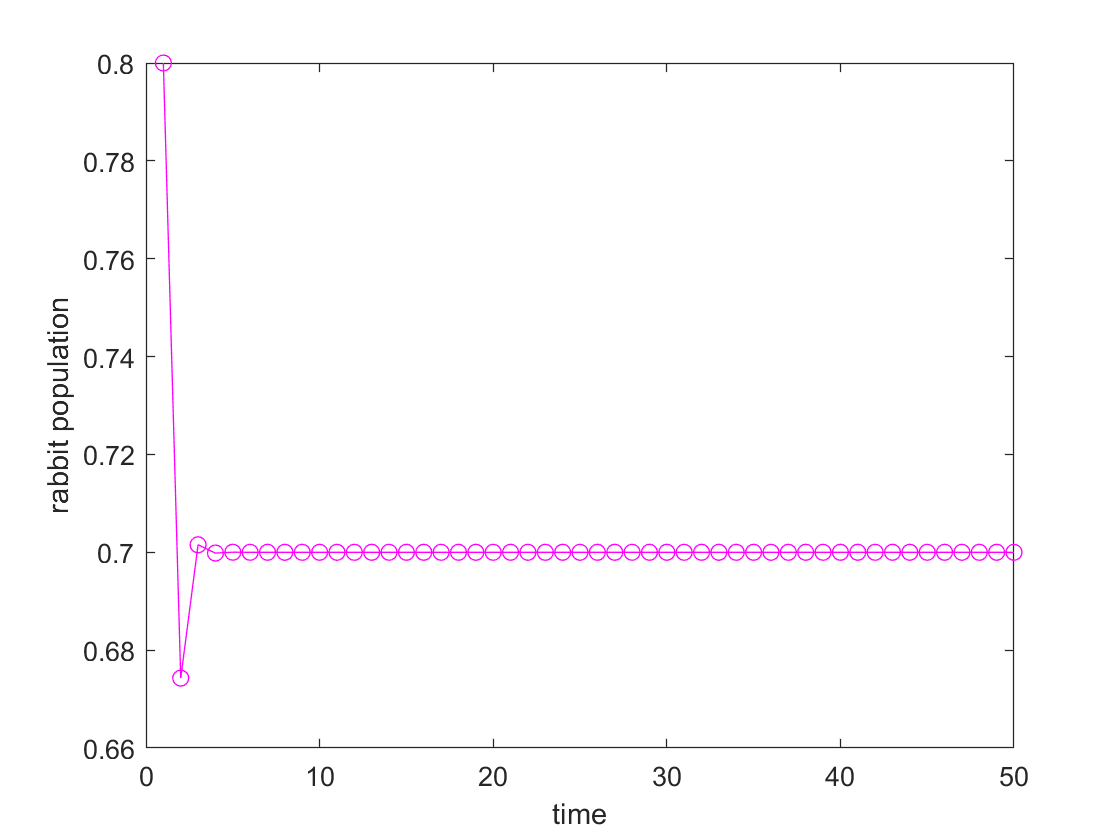

%part f - impossible
r = 1.1;
K = 0.7;
time_len = 1:50;

x = zeros(1, length(time_len));

%initial condition (i.e. starting population)
x(1) = 0.8;

for n = 1:length(time_len)-1
    x(n+1) = x(n) + r * (1 - x(n) / K) * x(n);
end
figure;
plot(time_len, x, '-om')
xlabel('time')
ylabel('rabbit population')

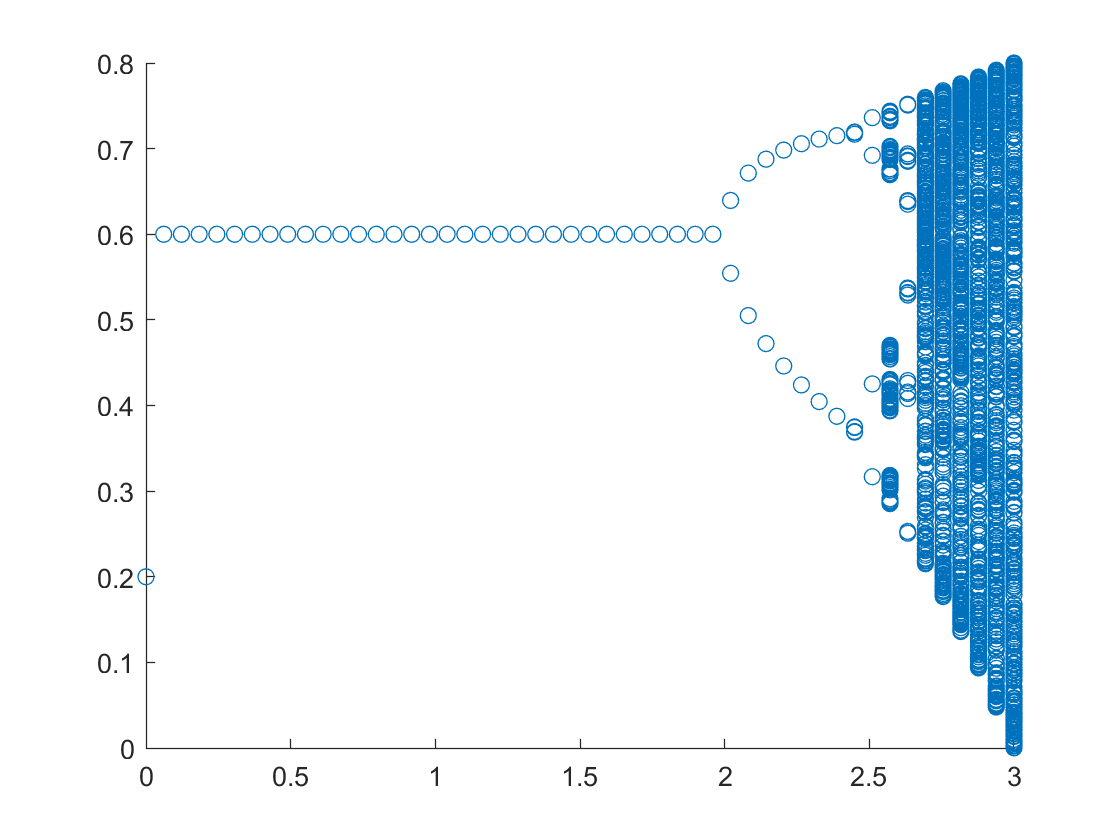

%part g
r = linspace(0.0, 3.0, 50);
K = 0.6;
n_max = 1000;
time_len = 1:n_max;

x = zeros(1, length(time_len));

%initial condition (i.e. starting population)
x(1) = 0.2;

r_vals = [];
x_vals = [];

figure; hold on;
half = n_max / 2;
for i = 1:length(r)
    for n = 1:length(time_len)-1
        x(n+1) = x(n) + r(i) * (1 - x(n) / K) * x(n);
    end
    r_vals = [r_vals, r(i)*ones(1,length(x(half:end)))];
    x_vals = [x_vals, x(half:end)];
end

scatter(r_vals, x_vals)